#### Resampling na 100 Gs/s

Korzystaj z plików z kopii zapasowej.

x100 = resample(x,100,10);

#### Korelacja

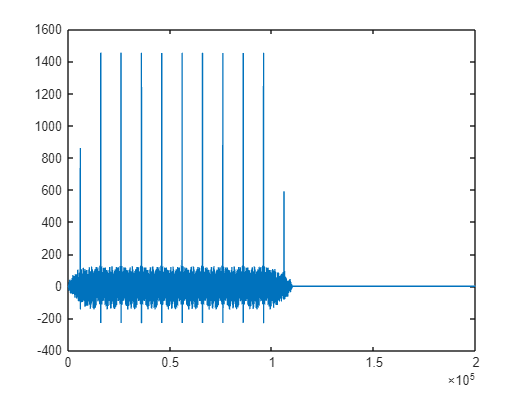

cor = xcorr(x100,gen100);
plot(cor);

#### Przycięcie

for i=15935:10000:85935
    nazwa_zmiennej = ['gen_cut' num2str((i-5935)/10000)]; 
    komenda = ['= gen100((' num2str(i) '-2000):(' num2str(i) '+9999-2000));'];
    eval([nazwa_zmiennej komenda]);
end

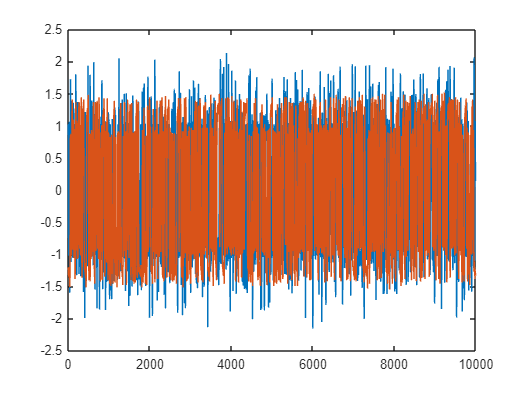

x100=x100./rms(x100);
for i=1:8
    nazwa_zmiennej = ['gen_cut' num2str(i)]; 
    komenda = ['= gen_cut' num2str(i) './rms(gen_cut' num2str(i) ');'];
    eval([nazwa_zmiennej komenda]);
end

figure(1)
plot(x100)
hold on
plot(gen_cut1)
hold off

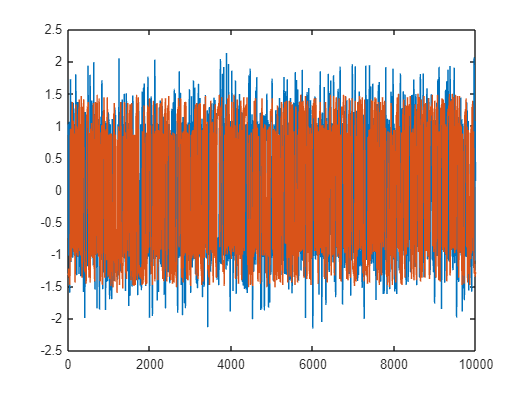

figure(2)
plot(x100)
hold on
plot(gen_cut2)
hold off

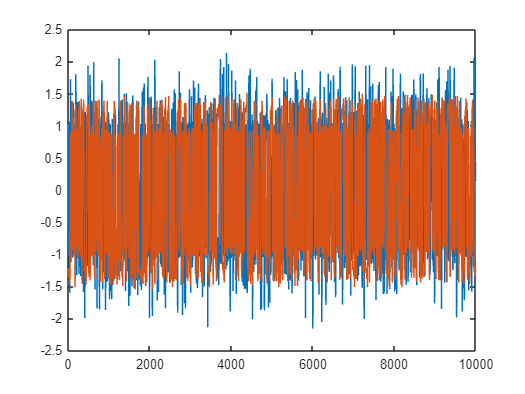

figure(3)
plot(x100)
hold on
plot(gen_cut3)
hold off

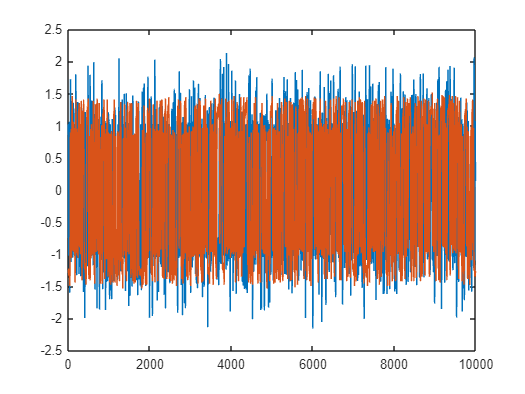

figure(4)
plot(x100)
hold on
plot(gen_cut4)
hold off

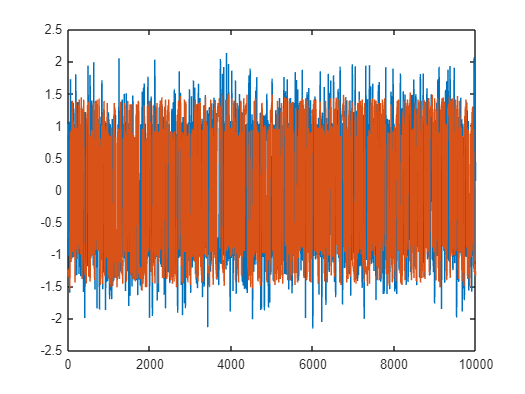

figure(5)
plot(x100)
hold on
plot(gen_cut5)
hold off

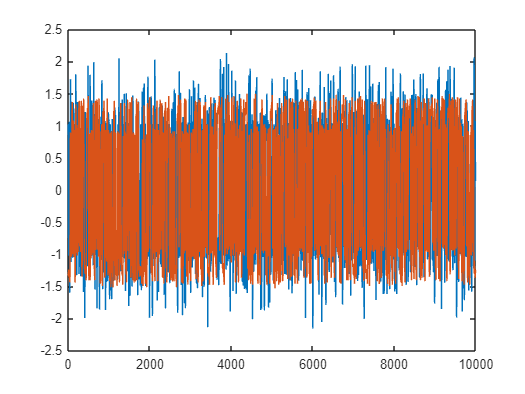

figure(6)
plot(x100)
hold on
plot(gen_cut6)
hold off

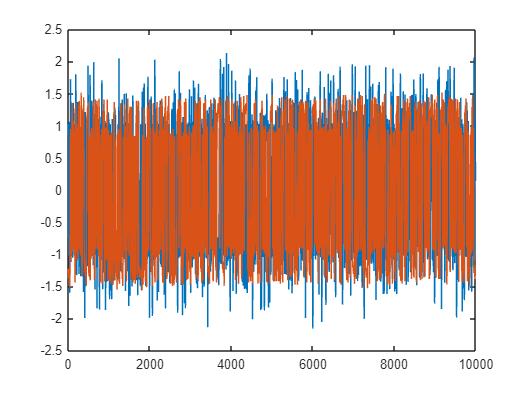

figure(7)
plot(x100)
hold on
plot(gen_cut7)
hold off

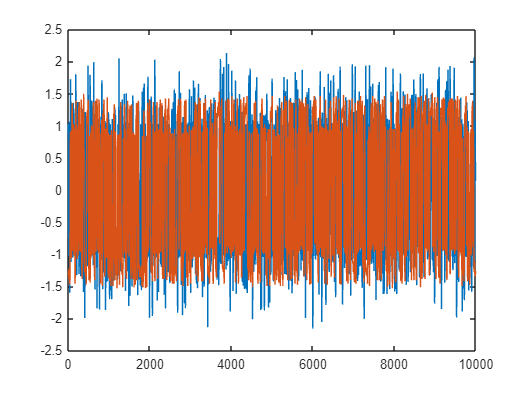

figure(8)
plot(x100)
hold on
plot(gen_cut8)
hold off

#### Zmiana fazy

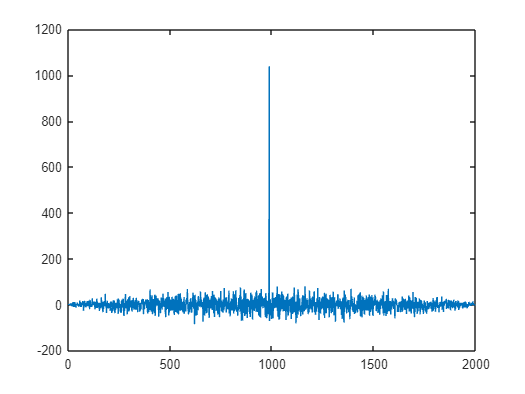

for i=1:8
    nazwa_zmiennej = ['gen_cut_ds' num2str(i)]; 
    komenda = ['= downsample(gen_cut' num2str(i) '(1:end),10);'];
    eval([nazwa_zmiennej komenda]);
end
cor = xcorr(x,gen_cut_ds8);
plot(cor)

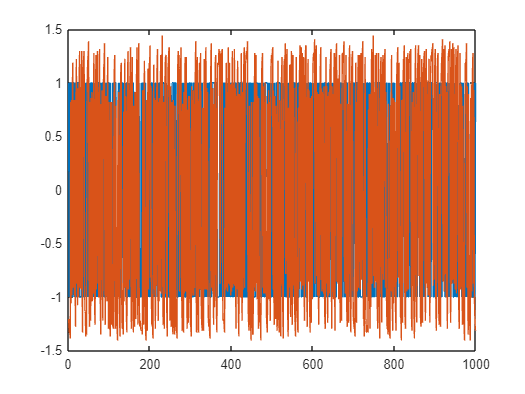

figure(9)
plot(x)
hold on
plot(gen_cut_ds1)
hold off

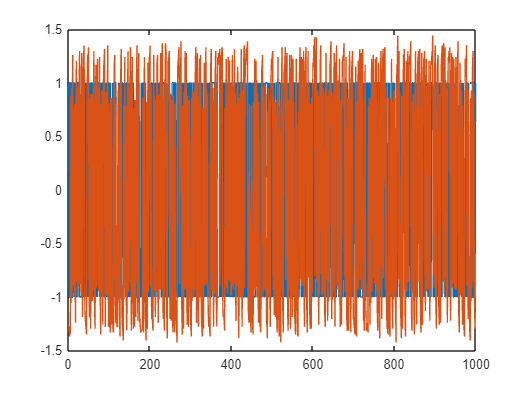

figure(10)
plot(x)
hold on
plot(gen_cut_ds2)
hold off

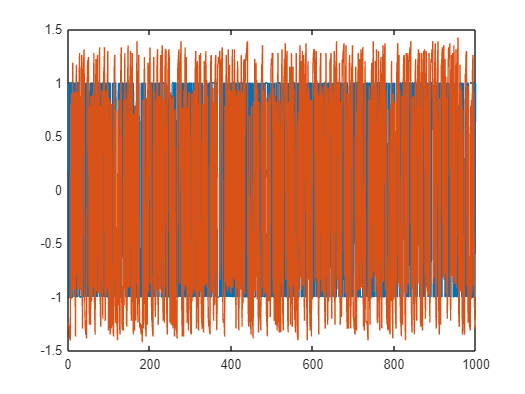

figure(11)
plot(x)
hold on
plot(gen_cut_ds3)
hold off

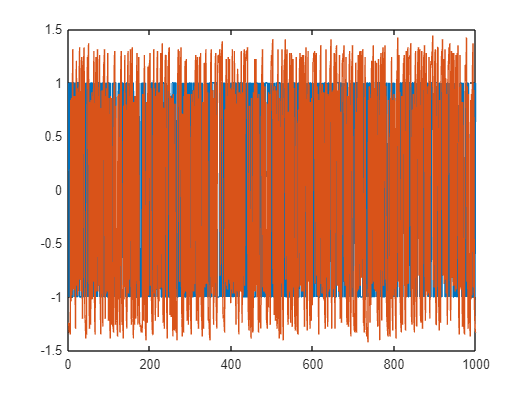

figure(12)
plot(x)
hold on
plot(gen_cut_ds4)
hold off

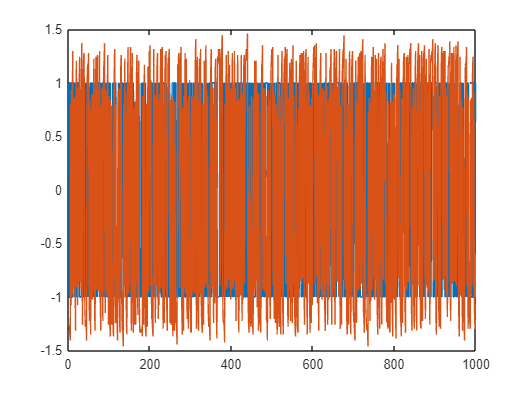

figure(13)
plot(x)
hold on
plot(gen_cut_ds5)
hold off

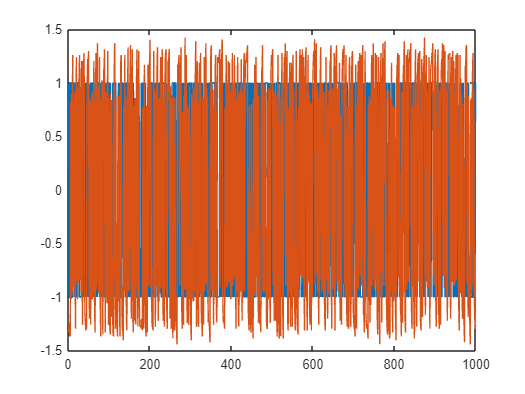

figure(14)
plot(x)
hold on
plot(gen_cut_ds6)
hold off

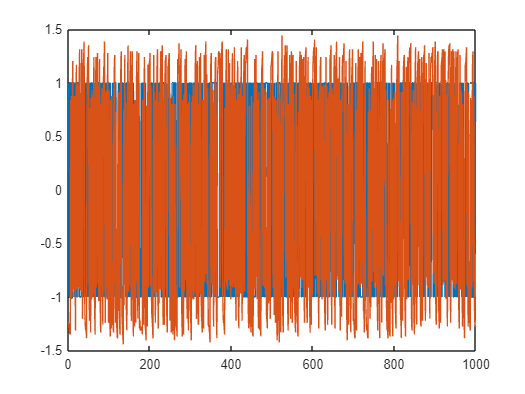

figure(15)
plot(x)
hold on
plot(gen_cut_ds7)
hold off

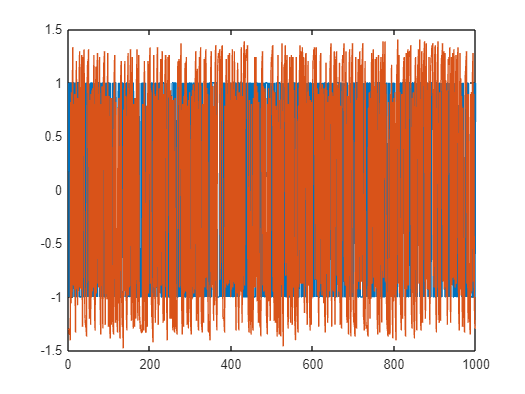

figure(16)
plot(x)
hold on
plot(gen_cut_ds8)
hold off

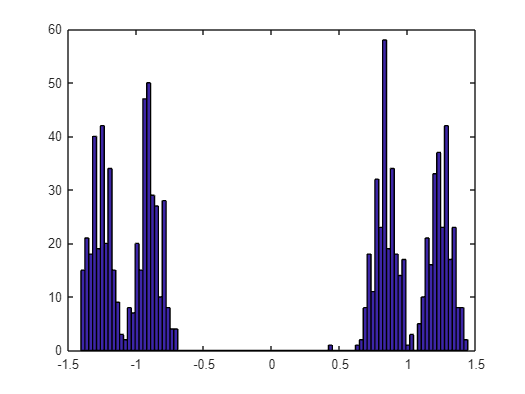

hist(gen_cut_ds1,100)

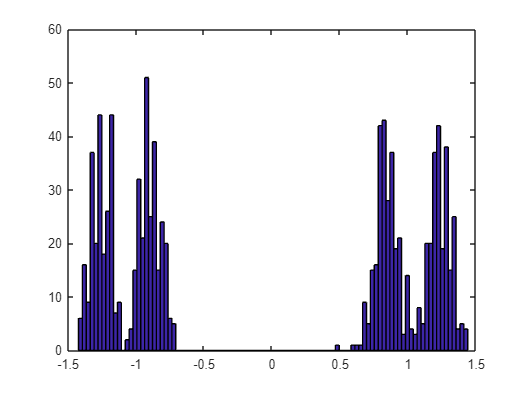

hist(gen_cut_ds2,100)

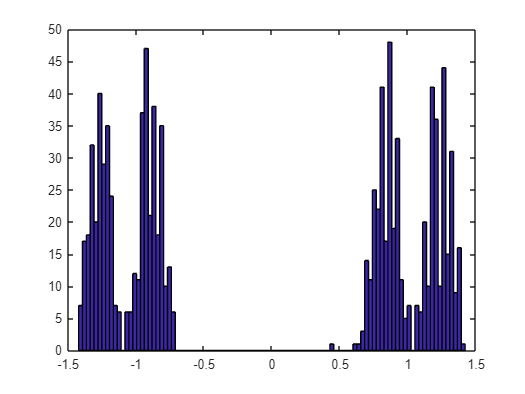

hist(gen_cut_ds3,100)

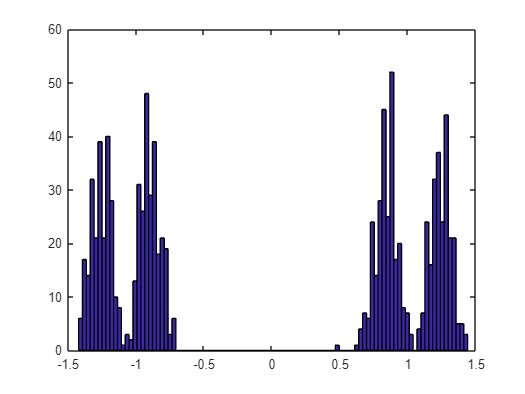

hist(gen_cut_ds4,100)

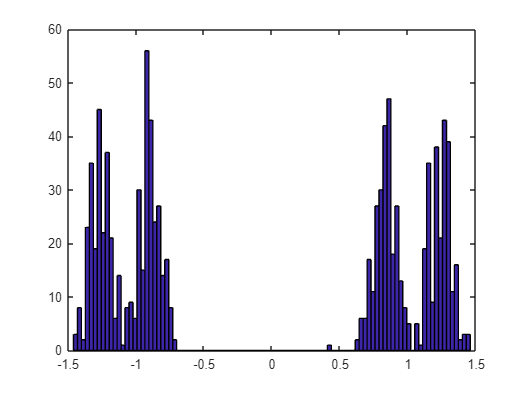

hist(gen_cut_ds5,100)

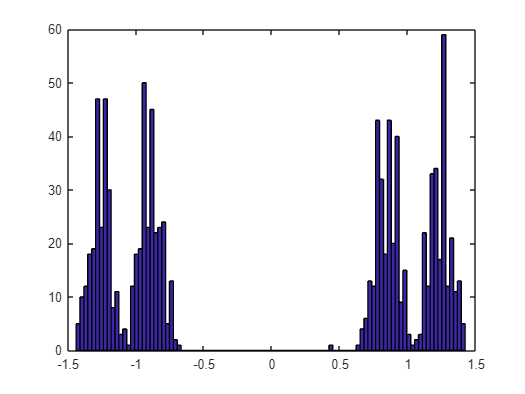

hist(gen_cut_ds6,100)

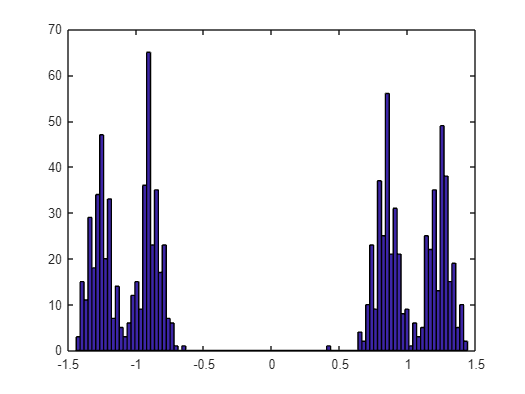

hist(gen_cut_ds7,100)

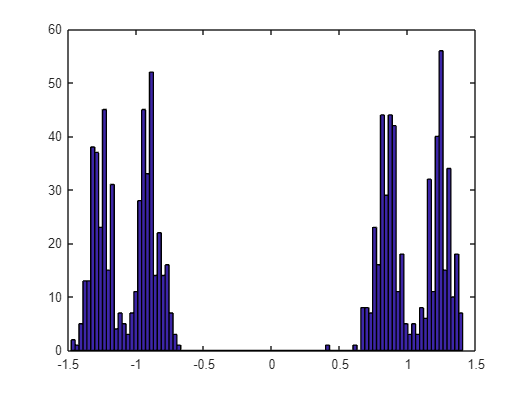

hist(gen_cut_ds8,100)

#### Zamiana na 0 i 1

x_norm = x+1;
x_norm = x_norm/2;
for i=1:8
    nazwa_zmiennej = ['gen_cut_ds_dig' num2str(i)]; 
    komenda = ['= dig(gen_cut_ds' num2str(i) ');'];
    eval([nazwa_zmiennej komenda]);
end

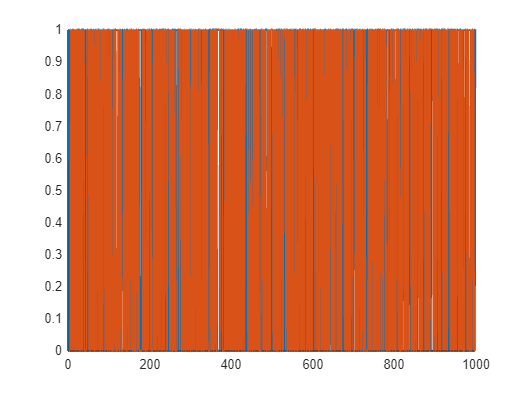

figure(17)
plot(x_norm)
hold on
plot(gen_cut_ds_dig1)
hold off

#### Sprawdzenie

for i=1:1000
    diff(i,1)=x_norm(i,1)-dig(i,1);
end

Error using cw3>dig
Too many input arguments.

plot(diff)



function gen_cut_ds_dig = dig(gen_cut_ds)
    gen_cut_ds_dig = ones(1000,1);
    
    for i=1:length(gen_cut_ds_dig)
        if gen_cut_ds(i,1) < 0
            gen_cut_ds_dig(i,1)=0;
        end
        if gen_cut_ds(i,1) > 0
            gen_cut_ds_dig(i,1)=1;
        end
    end
end